# Quickstart Guide: Custom Geometry

In this guide we are going to make a 2 neuron ball and stick (soma and single axon) model geometry

## Sections

The base of ELFENN geometries are sections: straight (or spherical) sections of neuron geometry. We will first define a spherical soma with a radius of 25 microns

soma = ELFENN.Section('soma', 'radius', 25,...
    'sectionLength', 50, 'nSeg', 1, 'sectionGeometry', 'S');

Next we'll define a 500 micron axon made up of 21 segments (discretized nodes)

axon = ELFENN.Section('axon', 'radius', 2.5, ...
    'sectionLength', 500, 'nSeg', 21);

## Cells

A cell is a collection of sections. Once a section is added to a cell the object is "cloned" meaning that changes to the section object will not propagate to the cell, or higher levels. Since both cells are the same we only need to create one cell object. For simplicity we will create the first cell and later rename it.

cell = ELFENN.Cell('cell1');

 We concatenate sections to the cell with the *connectsection* method.

cell.connectsection(soma, axon, [0,0,0]);

## Networks

To combine multiple cells, we create a *network: *a collection of cells aranged in space. 

network = ELFENN.Network();

To add cells we use the *addcell* method. For the next cell we will have to add an offset.

network.addcell(cell, [0,0,0]);

Much like sections, cells are also "cloned" meaning that to add the second cell we only need to change the name of the cell object and add it again.

cell.name = 'cell2';
offset = 100;
network.addcell(cell, [0,0, offset]);

Once the Geometry is finalized we "complete" the network. This lockes the geometry meaning that it cannot be changed (this protects against accidentally changing things). It also discretizes the cell allowing us to index sections.

network.complete()

## Results

In this guide we've created all the geometry required for our two cell model. We can display it with the following. For more information please see the quickstart guide for plotting or the detailed documentation.

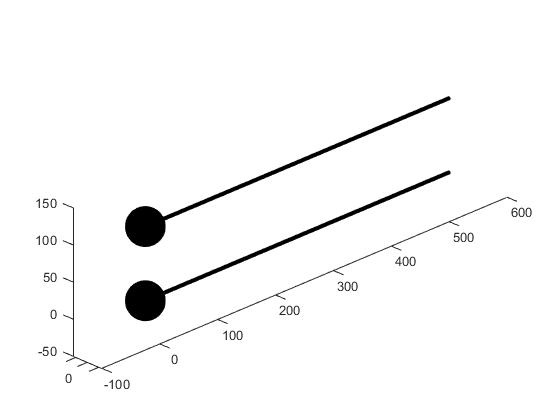

plotnetwork(network)
view([-45. 25])

## Interfacing with Networks

To interface with the network we access segments by their identifier - a number between 1 to n (total number of segments). ELFENN provides several helper function and properties to make this simple.

Firstly if we knew the exact cell, section and which segment it was we could get the ID by the following

id = network.getcellbyname('cell1').getsectionbyname('axon').segments(2).connectivityid;
disp(id);

     3



Since segment identifiers are typically "well ordered" it shoudnt be a surprise that the second segment of the first axon is the third segment in the network.

However it's rarely the case you know what element you want. Therefore we've made it easy to find the soma (if you have a section named soma), the tip (first compartment), and midpoint (middle compartment) of a cell or section;

id = network.getcellbyname('cell2').soma; disp(id);

    23



id = network.getcellbyname('cell1').tip; disp(id);

     1



id = network.getcellbyname('cell2').getsectionbyname('axon').tip; disp(id);

    24



id = network.getcellbyname('cell2').getsectionbyname('axon').mid; disp(id);

    34



There are also several ways to access compartments based on geometry/position. To find the closest compartment we use the *segmentclosestto* method which gives the cell name and segment handle to the segment closest to the specified point

[cell, segment] = network.segmentclosestto([50, 0, 0]); disp([cell, segment.connectivityid]);

    "cell1"    "3"



Sometimes one might want to know what two compartments are closest to a point (for example to add a gap junction near some coordinates). For this we use the *jumpclosestto* method. This gives the two closest segments - on two different cells closest to the specified point.

[cell1, cell2, seg1, seg2] = network.jumpclosestto([0,0,50]);
disp([cell1, seg1.connectivityid]);

    "cell1"    "1"



disp([cell2, seg2.connectivityid]);

    "cell2"    "23"

